clearvars; close all;
syms x y xr yr xo yo x0 y0 m
syms d h positive

%Senza perdita di generalitá impongo che il robot si trovi nell'origine
xr = 0; yr = 0;
%1° condizione:impongo che la circonferenza sia tangente alla direzione del robot
x0 = -m*y0;
%Impongo che la circonferenza di raggio d centrata in Omega passi dal robot
d = sqrt((xr-x0)^2 + (yr-y0)^2);
%2° condizione:impongo che la circo in Omega sia tangente alla circo in obst
eq = (x0-xo)^2 + (y0-yo)^2 == (d+h)^2;
sol = solve(eq,y0);

% m = tan(0); xr = 12.48; yr = 17.73; xo0 = 15; yo0 = 15; h = 2;
m = tan(1.5708); xr = 5; yr = 3.8574; xo0 = 5.9; yo0 = 5; h = 0.8;
% m = tan(0.9524); xr = 3.43; yr = 3.25; xo0 = 4; yo0 = 5; h = 0.85;
% m = tan(2.4292); xr = 5.82; yr = 4.70; xo0 = 3.9; yo0 = 4.9; h = 0.97;
xo = xo0 - xr; yo = yo0 - yr;
yOmega = double(subs(sol(1)));
xOmega = double(-m*yOmega);
dOmega = double(sqrt(xOmega^2 + yOmega^2));

Plotting

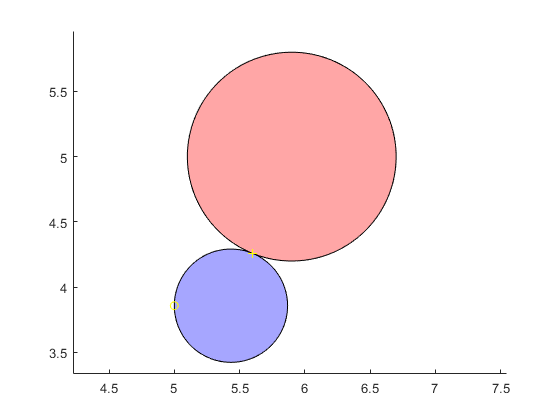

yOmega = yOmega + yr; xOmega = xOmega + xr; xo = xo0; yo = yo0;
omega = nsidedpoly(2000, 'Center', [xOmega yOmega], 'Radius', double(dOmega));
plot(omega, 'FaceColor', 'b'); hold on;  axis equal;
obst = nsidedpoly(2000, 'Center', [xo yo], 'Radius', double(h));
plot(obst, 'FaceColor', 'r'); hold on;
centerDir = [xo,yo]-[xOmega,yOmega];
centerDir = centerDir/norm(centerDir);
P1 = [xOmega yOmega] + dOmega*centerDir;
plot(P1(1),P1(2),"+y"); plot(xr,yr,"oy");